# BRDF visualization

20220406  y.yoshimura

(c) 2022 yasuhiro yoshimura

clc
clear
cls

## object parameters

sat.pos = [0 0 0]; % position vector
sat.normal = [0 0 1]; % normal vector
sat.area = 1; % area, m^2

sat.F0 = 0.5;
sat.rho = 0.5;
sat.Cd = 0.5;

### for Ashikhmin–Shirley model

sat.nu = 1000; % 100 or 800
sat.nv = 500;
sat.uu = [0 1 0];
sat.uv = [1 0 0];

### for Cook–Torrance model

sat.mCT = 0.1; % roughness parameter

## illumination condition

% sun direction
phiI = deg2rad(-90);
thetaI = deg2rad(30);
s = [cos(phiI) * sin(thetaI), sin(phiI) * sin(thetaI), cos(thetaI)];

% reference vector
azi = 0:deg2rad(2):2*pi;
ele = 0:deg2rad(2):pi/2;
[phiR, thetaR] = meshgrid(azi, ele);

x = cos(phiR) .* sin(thetaR);
y = sin(phiR) .* sin(thetaR);
z = cos(thetaR);

% perfect specular direction
rRef = 2 * (s * sat.normal') * sat.normal - s; % 1x3

## true AS model

D = zeros(size(phiR));
for i = 1:size(phiR,1)
    for j = 1:size(phiR, 2)
        phi = phiR(i,j);
        theta = thetaR(i,j);
        % reference vec.
        v = [cos(phi) * sin(theta), sin(phi) * sin(theta), cos(theta)];

        [~, ~, D(i,j)] = brdfAS(sat, s, v);

    end
end

## show figs

on hemisphere

l = 1.5; % arrow scale

figure
figSurf = surf(x, y, z, D, 'edgecolor', 'none')

figSurf =   Surface のプロパティ:

       EdgeColor: 'none'
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [46×181 double]
           YData: [46×181 double]
           ZData: [46×181 double]
           CData: [46×181 double]

  すべてのプロパティ を表示


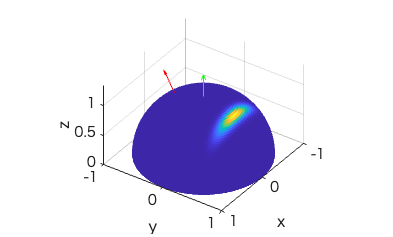

% colorbar
% alpha 0.4
axis equal
hold on
quiver3(0,0,0, l*s(1), l*s(2), l*s(3), 'r')
quiver3(0,0,0, l*sat.normal(1), l*sat.normal(2), l*sat.normal(3), 'g')
xlabel('x'), ylabel('y'), zlabel('z')
view([270+rad2deg(phiI) 30])
view([124.61 34.81])


% figure
% contourf(cos(phiR).*sin(thetaR), sin(phiR).*sin(thetaR), D);
% hold on
% plot(vNominal(1), vNominal(2), 'yx')
% colorbar
% axis equal
% xlabel('x'), ylabel('y')